# BMMO Model - Change KA Actuation options

In this document, we show how to change the settings for KA actuation settings of the BMMO model. For more details on the BMMO model see the functional EDS ([D000810611](https://tc.asml.com/#/com.siemens.splm.clientfx.tcui.xrt.showObject?uid=xOp1Eoq$QS4FxA)).  

## Getting started

We first need to simulate the BMMO model on TwinScan using Matlab ,and therfore need to load an additional module: the BMMO-XY module.

module.include('\\asml.com\eu\shared\nl011052\DE_Metro_tools\EUV\releases\BMMO-XY', ...
    '-sameNameControl', 'skip');

Dependent module: DE_Overlay_Models                                                                R2022-06-08 (\\asml.com\eu\shared\nl011065\MO_tools\DE_Overlay_Models)
Including module: BMMO-XY                                                                          R2022-05-06 (C:\Users\ammoradi\AppData\Roaming\MathWorks\MATLAB\ModulesCache\C5782B2E64FECDCC\R2022_05_06\BMMO-XY)


module.include('\\asml.com\eu\shared\nl011052\DE_Metro_tools\EUV\releases\CET_model', ...
    '-sameNameControl', 'skip');
module.include('\\asml.com\eu\shared\nl011032\Projection_tooling\projection_toolbox_p', ...
    '-sameNameControl', 'skip');

## Loading data

As in the 'Getting Started',  we will use the 2 example zips shown below. 

zip_dir = '\\asml.com\eu\shared\nl011052\DE_Metro_tools\EUV\etc\BMMO-NXE\';
zip_path_bmmo = [zip_dir 'Litho_InSight_Job_ID_14625_TC04.zip'];
zip_path_bl3  = [zip_dir 'Litho_InSight_Job_ID_9447_TC01b.zip'];

we then will load the input structure and the sbc recipe that was generated.

[input_struct_bmmo, ~, sbc_out_bmmo] = bmmo_read_lcp_zip(zip_path_bmmo);

Unzipping \\asml.com\eu\shared\nl011052\DE_Metro_tools\EUV\etc\BMMO-NXE\Litho_InSight_Job_ID_14625_TC04.zip
Finding ADELs
Parsing LIS ADELs:
Parsing ADELbmmoOverlayJobReport
Parsing ADELsbcOverlayDriftControlNxe
Reading ADELmetrology
Reading WIDs
    {'AI3AB181MM'}    {'AI3AB222MM'}    {'AI3AB223MM'}    {'AI3AB224MM'}

Mapping WIDs from Job report to ADELmetrology
Applying WEC
Mapping WEC files:
Wafer 1: ADELwaferErrorCorrection_AI3AB181MM_LS_OV_RINT_WEC_AI3AB181MM_LS_OV_RINT_20180612_1256_DCM_V42.xml
Wafer 2: ADELwaferErrorCorrection_AI3AB222MM_LS_OV_RINT_WEC_AI3AB222MM_LS_OV_RINT_20180612_1256_DCM_V42.xml
Wafer 3: ADELwaferErrorCorrection_AI3AB223MM_LS_OV_RINT_WEC_AI3AB223MM_LS_OV_RINT_20180612_1256_DCM_V42.xml
Wafer 4: ADELwaferErrorCorrection_AI3AB224MM_LS_OV_RINT_WEC_AI3AB224MM_LS_OV_RINT_20180612_1256_DCM_V42.xml
Subtracting WEC offsets
Reading expinfo
Mark type: BF3u2V
Applying exposure wafer sort order using customer manual mapping and ADELler
     1     2     3     4

Reading 

[input_struct_bl3, ~, sbc_out_bl3] = bmmo_read_lcp_zip(zip_path_bl3);

Unzipping \\asml.com\eu\shared\nl011052\DE_Metro_tools\EUV\etc\BMMO-NXE\Litho_InSight_Job_ID_9447_TC01b.zip
Finding ADELs
Parsing LIS ADELs:
Parsing ADELbmmoOverlayJobReport
Parsing ADELsbcOverlayDriftControlNxe
Reading ADELmetrology
Reading WIDs
    {'GFQ4B172MM'}    {'GFQ4B171MM'}    {'GFQ4B170MM'}    {'GFQ4B193MM'}

Mapping WIDs from Job report to ADELmetrology
Applying WEC
Mapping WEC files:
Wafer 1: ADELwaferErrorCorrection_GFQ4B172MM_LS_OV_RINT_WEC_GFQ4B172MM_LS_OV_RINT_20201014_1116_DCM_V42b.xml
Wafer 2: ADELwaferErrorCorrection_GFQ4B171MM_LS_OV_RINT_WEC_GFQ4B171MM_LS_OV_RINT_20201014_1116_DCM_V42b.xml
Wafer 3: ADELwaferErrorCorrection_GFQ4B170MM_LS_OV_RINT_WEC_GFQ4B170MM_LS_OV_RINT_20201014_1116_DCM_V42b.xml
Wafer 4: ADELwaferErrorCorrection_GFQ4B193MM_LS_OV_RINT_WEC_GFQ4B193MM_LS_OV_RINT_20201014_1116_DCM_V42b.xml
Subtracting WEC offsets
Reading expinfo
Mark type: BF3u2V
Applying exposure wafer sort order using customer manual mapping and ADELler
     1     2     3     4

Read

### Input structure

As mentioned in the 'Getting Started' page, when creating the input structure from a zip file, it sets the configuration of the model to be the same as the original job the customer ran on OTAS/LIS.

input_struct_bmmo.info.configuration_data

ans = struct with fields:
                   platform: 'LIS'
    susd_correction_enabled: 0
      KA_correction_enabled: 1
           intraf_actuation: 5


input_struct_bl3.info.configuration_data

ans = struct with fields:
                   platform: 'LIS'
    susd_correction_enabled: 1
      KA_correction_enabled: 1
                  bl3_model: 1
           intraf_actuation: 5
               KA_actuation: 'HOC'


As you can see below the KA actuation has two defined options the higher order corrections (KA_HOC) and Lower order corrections (KA_LOC) (KA_HOC and KA_LOC explaned in D000323759). In this example the KA actuation is set to HOC, normally accompanied with 5th order / version 3 or version 5 in the actuation. To show how to do that manually or change between the options, we make the ml structure and pick the options from the input_structs. 

[mli_bmmo, options_bmmo] = bmmo_process_input(input_struct_bmmo);
[mli_bl3, options_bl3] = bmmo_process_input(input_struct_bl3);

Then based on whether we want to achieve an actuation or prediction fingerprint of the KA model, we can change the function handle in the options. Actuation_type is a scanner property/setting independent of what Baseliner/BMMO wants. VERSION_5 corresponds to default NXE:3600D, VERSION_3 is only used for NXE:3600D_ES, FIFTH_ORDER is the one used on NXE:3400C and THIRD_ORDER is the original NXE:3400 value (still used on a few systems only). The system must be at least FIFTH_ORDER to be able to use KA_HOC. For details on changing actuation_type using configurable objects you can check the bmmo_help_inline_SDM.

## KA_HOC Actuation

options_bl3.KA_actuation.fnhandle = @bmmo_KA_HOC_fingerprint;
options_bl3.KA_actuation.type = 'VERSION_5';

Using the KA_SBC finger print function, we can perform the KA_actuation and for the input, we need to provide ml structure of the input data, the SBC grid data generated from read_LCP_zip function and the options picked by bmmo_process_input:

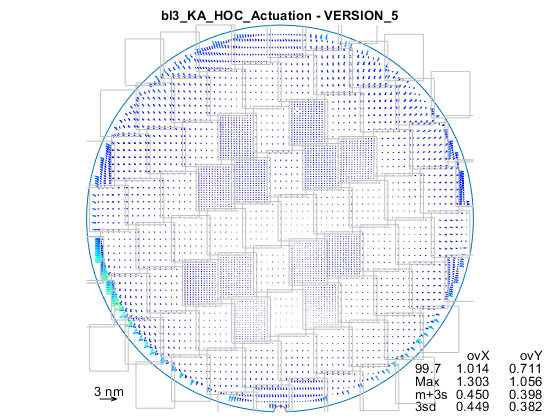

ans =   Figure (vector) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


[bl3_KA_actuation,bl3_ml_res] = bmmo_KA_SBC_fingerprint(mli_bl3, sbc_out_bl3.KA.grid_2de, options_bl3);
ovl_plot(bl3_KA_actuation,'vcolor','scale',3,'legend','cust','brickwall', ...
    'prc',3,'title', 'bl3_KA_HOC_Actuation - VERSION_5')

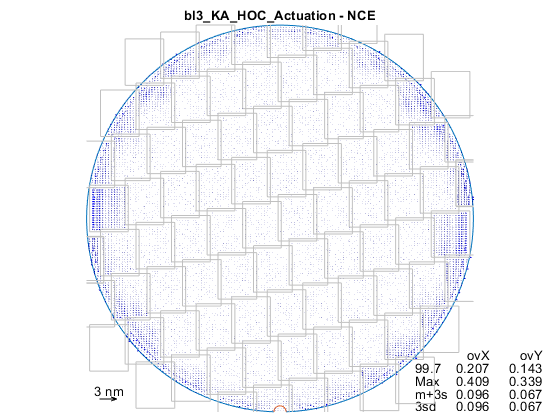

ans =   Figure (vector) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


ovl_plot(bl3_ml_res,'vcolor','scale',3,'legend','cust','brickwall', ...
    'prc',3,'title', 'bl3_KA_HOC_Actuation - NCE')

## KA_HOC Prediction

To create the KA_HOC prediction there is no options for the actuation_type to change. For the function handle, the KA_33par fingerprint should be set. Then we are allowed to run the KA_SBC fingerprint.

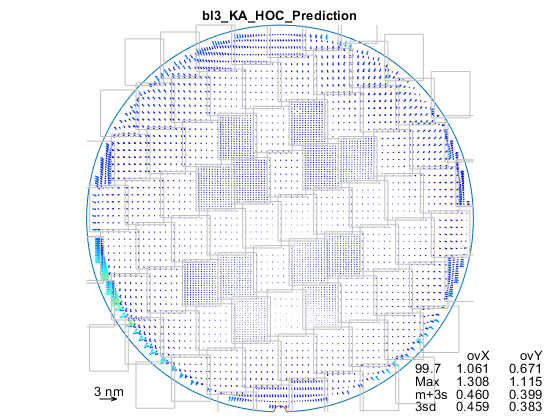

ans =   Figure (vector) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


options_bl3.KA_actuation.fnhandle = @bmmo_KA_33par_fingerprint;
[bl3_KA_prediction,bl3_ml_res_P] = bmmo_KA_SBC_fingerprint(mli_bl3, sbc_out_bl3.KA.grid_2de, options_bl3); 
figure;
ovl_plot(bl3_KA_prediction,'vcolor','scale',3,'legend','cust','brickwall', ...
    'prc',3,'title', 'bl3_KA_HOC_Prediction')

### KA_HOC Actuation vs Prediction

The difference between the HOC actuation and prediction calculation can be seen below:

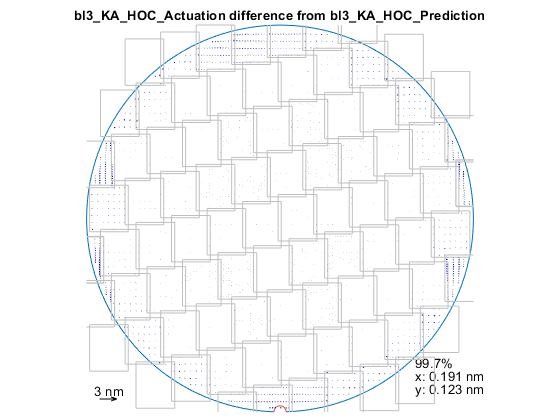

ans =   Figure (vector) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


delta_HOC_actu_pre = ovl_sub(bl3_KA_actuation, bl3_KA_prediction);
figure;
ovl_plot(delta_HOC_actu_pre,'vcolor','scale',3,'brickwall', ...
    'prc',3,'title', 'bl3_KA_HOC_Actuation difference from bl3_KA_HOC_Prediction') 

## KA_LOC Actuation

The KA_LOC actuation is done only on BMMO NXE, so therefor we use the bmmo_KA_actuation (type and function handle) and the option for actuation is the KA_LOC_CET fingerprint.

options_bmmo.KA_actuation.fnhandle = @bmmo_KA_LOC_CET_fingerprint;
options_bmmo.KA_actuation.type = 'VERSION_3';

note: if you do not add the actuation.type, there will be an error  informing about the options for the actuation.type

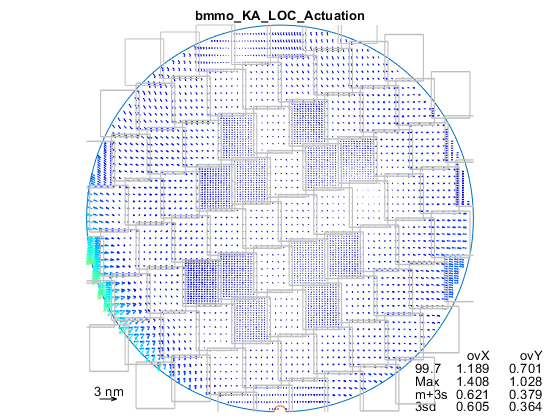

ans =   Figure (vector) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


[bmmo_KA_LOC_actuation,bmmo_ml_res] = bmmo_KA_SBC_fingerprint(mli_bmmo, sbc_out_bmmo.KA.grid_2de, options_bmmo);
ovl_plot(bmmo_KA_LOC_actuation,'vcolor','scale',3,'legend','cust','brickwall', ...
    'prc',3, 'title', 'bmmo_KA_LOC_Actuation')

## KA_LOC Prediction

For KA_LOC prediction the KA_LOC fingerprint is set for the function handle.

options_bmmo.KA_actuation.fnhandle = @bmmo_KA_LOC_fingerprint;
[bmmo_KA_LOC_prediction,bmmo_ml_res] = bmmo_KA_SBC_fingerprint(mli_bmmo, sbc_out_bmmo.KA.grid_2de, options_bmmo);